# A different version of figure 3 in the poster, but for each run within each condition

this plots changes in network props at each and every time point. each plot only shows this within a single condition, which is not what was used in the poster. you can ignore this, or maybe come back to it later. for now it doesnt really fit the approach that i have with the analysis.

# The Data Set 

%Generate Master Data Set
% First retreive Master Data Set
close all force
cog_task_list = {'PVT', 'GoNogo', 'Math'}; % code only works with PVT Math and Gonogo
DF = dfmaster('cogtestlist',cog_task_list);


Getting GPSD during PVT Task. . . . . . . . . . . . -done

Getting Network Props during PVT: . . . . . . . . . . . . -done

Getting GPSD during GONOGO Task. . . . . . . . . . . . -done

Getting Network Props during GONOGO: . . . . . . . . . . . . -done

Getting GPSD during MATH Task. . . . . . . . . . . . -done

Getting Network Props during MATH: . . . . . . . . . . . . -done


# ANALYSIS NAME

# Summary

Lets start with two tasks that have different levels of clusring during presleep: gonogo and PVT, in which clustering is larger for gonogo than that during pvt.

in this scenerio after waking without blue light , except at t=1, clustering is the same during both tasks. im not sure if gonogo decreased or math decreased, just that both are the same some 30 minutes after abrupt waking. Like other effects ive seen, its off that this occurs after t=1, where the effects of flseep inertia should be at their highest.

interestingly when instead, exposed to blue light after waking, the difference is no longer there. that is, the difference in clustering between tasks 'reverts' back to the difference seen during presleep. in some sense the intervention does something to retain the difference between tasks. 

### **Gonogo vs PVT**

During presleep clustering in the delta band increases when switching from the PV task to the GOnogo task, 

- the effect is highly significant

Under control, immediately after waking at t=1 , clustering is higher during gonogo vs PVT, but tend to be similar for the remaining time points

- at time 1  clustering in gonogo task again is higher than PVT.

- at time 2 , and 4, delta clustering reverts back to PVT levels, (although it is just barely significant different at time 3; but note that this may be due to small sameple size of gonogo)

Under blue light, clustering during the PV and gonogo task are always different.

Notes

during sleep inertia, under control, clustering becomes similar during both tasks. However, it is off that immediately after waking during control clustering is higher during gonogo, howver, for the remaining time points, it seems to revert back to the same levels. 

Blue light might 'maintain' the difference in clusterin between the two tasks observed during presleep. 

### GoNogo vs Math

During presleep GONOGO and MATH are the same, although the effect is almost significant

again this may be due to the small sample sizes of both tasks (n=9 in both cases)

- another reason that this lack of a difference is merely a consequence of error is that however, PVT and math also have similar clustering during presleep. 

- basically its difficult to understand why pvt and and gonogo are the same as math, but gonogo is different from pvt,

- this complicates things, and it may be considered to toss out either gonogo or math for this analysis 

however, if the difference this contrasts the difference seen in gonogo and pvt. 

- this may imply that some similar mechanisms are at play during both gonogo and math, but may be different during gonogo and pvt.

During control, at all time points, clustering is the same during these two tasks

- in other words, sleep inertia did not impact the difference in clustering observed during presleep

During blue light, go nogo clustering is higher than math only at the first time point

- in this case, the intervention DID screw with the differences between these tasks,

- note that its difficulat to say if there was an increase in go nogo, or decrease in math. more tests are needed for this claim to be made

### PVT vs Math

During presleep, PVT and Math have same clustering

During control, clustering is much larger during math than PVT only during the early time points after wake

- there are highly sig different at t = 1 and 2

- they are similar (as in presleep levels) after time 3 and 4

- however note they are slightly significant during time 2 as well

- basically it looks like sleep inertia alters the difference in clustering between PV task and Math task 

During blue light, clustering is higher during math than PVT in 3 of the 4 time points (except at t=2)

- similar to the effects observed between Gonogo and Math, sleep ineria increases the difference in clustering between these two tasks.

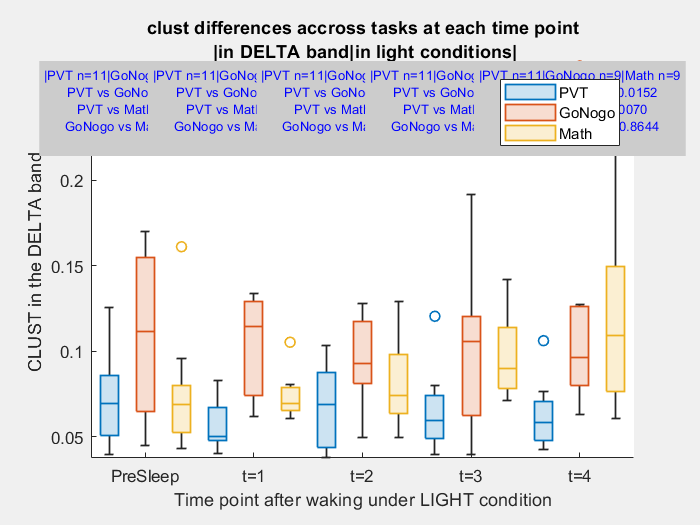

clearvars -except DF
ntwprop = 'clust';
condition = 'light';
fsband = {'delta'};
removemathtask = false; % you can ignore the math task analysis (for TAB poster)
clc
close all; figure("Visible","on")
testtasks(DF,ntwprop,condition,fsband, removemathtask = removemathtask) 

# Functions

function df_grouped = getgroupeddf(DF, ntwprop, condition,band, opts)
    arguments
        DF
        ntwprop 
        condition
        band
        opts.time
        opts.removemathtask = false;
    end

    if strcmp(condition,'baseline') 
        opts.time = 0;
    end

    extdf = @(cogtask, sbj) DF( ...
        (DF.cogtest == cogtask) &...
        (DF.ntwprop == ntwprop)  &...
        (DF.condition == condition) &...
        ismember(DF.sbj, sbj) &...
        ismember(DF.run, opts.time) &...
        ismember(DF.band_ord,band),:);
    
    
    df_pvt      = extdf('PVT', goodsbj('PVT'));
    df_gonogo   = extdf('GoNogo', goodsbj('GoNogo'));

    if opts.removemathtask
        df = [df_pvt;df_gonogo]; 
        df = dfrmcats(df);
        df.cogtest = reordercats(df.cogtest, {'PVT','GoNogo'});        
    else
        df_math     = extdf('Math', goodsbj('Math'));
        df = [df_pvt;df_math;df_gonogo]; 
        df.cogtest = reordercats(df.cogtest, {'PVT','GoNogo', 'Math'});            
    end
    
    df_grouped = varfun(@mean, df, "InputVariables","Y","GroupingVariables",["cogtest","condition","run","sbj","band_ord"]);
    df_grouped = renamevars(df_grouped, 'mean_Y',ntwprop);    
    df_grouped = dfrmcats(df_grouped);

end

Function to Test Task Pairs at each time point

function testtasks(DF,ntwprop, condition, fsband, ax,opts)
    arguments
        DF
        ntwprop
        condition
        fsband
        ax = nexttile;
        opts.removemathtask = false;
    end
    % note this function only compares pvt, math and gonogo
    taski = 'PVT';
    taskj = 'GoNogo';
    taskk = 'Math';
    ax.NextPlot = 'add';

    df_bl = getgroupeddf(DF, ntwprop, 'baseline', fsband, removemathtask = opts.removemathtask);
    df_cnd = getgroupeddf(DF, ntwprop, condition, fsband, time=1:4, removemathtask = opts.removemathtask);
    df = [df_bl;df_cnd];

    boxchart(df.run, df.(ntwprop), 'GroupByColor', df.cogtest)
  
    if strcmp(condition, 'baseline')
        t_set = 0;
    else
        t_set = 0:4;
    end

    for t = t_set
        task_i_df = df.(ntwprop)(df.cogtest == taski & df.run == t);
        task_j_df = df.(ntwprop)(df.cogtest == taskj & df.run == t);
        task_k_df = df.(ntwprop)(df.cogtest == taskk & df.run == t);
    
        [~,pij] = ttest2(task_i_df, task_j_df);
        [~,pik] = ttest2(task_i_df, task_k_df);
        [~,pjk] = ttest2(task_j_df, task_k_df);
        
        effectinfo{1} = sprintf('|%s n=%d|%s n=%d|%s n=%d',taski, numel(task_i_df),taskj, numel(task_j_df), taskk, numel(task_k_df));    
        effectinfo{2} = sprintf('%s vs %s p=%.04f',taski,taskj, pij);
        effectinfo{3} = sprintf('%s vs %s p=%.04f',taski,taskk, pik);
        effectinfo{4} = sprintf('%s vs %s p=%.04f',taskj,taskk, pjk);
       
        ymax = max(df.(ntwprop));
        text(ax, t,ymax, sprintf('%s\n', effectinfo{:}),'FontSize',8,'Color','b','BackgroundColor', [.8 .8 .8],'VerticalAlignment','top', 'HorizontalAlignment','center');
        hold on;
        figure(gcf)
    end

    ylabel(sprintf('%s in the %s band', upper(ntwprop),upper(fsband{:})))

    ax.XTick = 0:4;
    ax.XTickLabel= {'PreSleep', 't=1','t=2','t=3','t=4'};
    xlabel(sprintf('Time point after waking under %s condition', upper(condition)));
    title(sprintf('%s differences accross tasks at each time point\n |in %s band|in %s conditions|',ntwprop,upper(fsband{:}),condition));    
       
    axis tight
    legend

end